load('CYLINDER_ALL.mat')
X=VORTALL(:,1:end-1);
Y=VORTALL(:,2:end);
[U S V]=svd(X,'econ')

U =    -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0

S = 	1.0e+03 *

    3.5639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.2990         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =     0.0817   -0.0452    0.1074    0.0090   -0.1171    0.1153    0.0389   -0.0383   -0.1092    0.1142   -0.0264    0.1162   -0.0305    0.1170   -0.0116    0.1131   -0.0100   -0.1027   -0.0455    0.0999    0.0515   -0.0730   -0.0865   -0.0426   -0.1055   -0.0671   -0.0923   -0.1131   -0.0096   -0.1012    0.0209   -0.0339    0.0983   -0.0701    0.0798   -0.0771   -0.0735    0.0917    0.0524   -0.0902   -0.0514   -0.0614   -0.0870   -0.0231   -0.0926    0.0993   -0.0294    0.0801   -0.0692    0.0111
    0.0818   -0.0670    0.0957    0.0550   -0.1048    0.1132   -0.0337   -0.1023   -0.0430    0.0734    0.0810    0.0580    0.0983    0.0168    0.1163   -0.0295   -0.1125    0.0810   -0.0834   -0.0990    0.0625    0.1171    0.0030    0.0989    0.0613    0.1000    0.0584    0.1142   -0.0139    0.1030   -0.0215    0.0533   -0.0903    0.0952   -0.0449    0.1023    0.0132   -0.0954    0.0348    0.0826   -0.0581   -0.0551    0.0575   -0.0202    0.0719    0.0675    0.0693    0.0185   -0.0325   -0

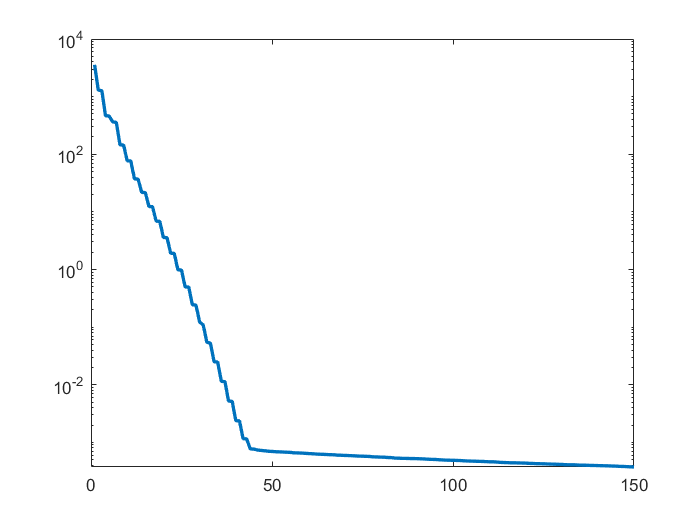

semilogy(diag(S),'linewidth',2)
xlim([0 150])
ylim([0 10000])

r=100;
U=U(:,1:r);
S=S(1:r,1:r);
V=V(:,1:r);
A=U'*Y*V*inv(S)

A =     1.0000   -0.0009   -0.0001   -0.0083   -0.0069    0.0008    0.0000   -0.0013    0.0014    0.0002   -0.0000   -0.0014    0.0007    0.0001   -0.0000    0.0002    0.0021   -0.0000    0.0001    0.0011    0.0002   -0.0000    0.0000    0.0012   -0.0012    0.0000   -0.0002    0.0015    0.0001    0.0005    0.0000   -0.0001    0.0001   -0.0005   -0.0007    0.0031    0.0032   -0.0094    0.0028    0.0200   -0.0013    0.0257    0.0056   -0.0174    0.0201    0.1035    0.1020   -0.0001    0.0107   -0.0464
    0.0009    0.9778   -0.2095   -0.0000    0.0011   -0.0401    0.0137   -0.0001    0.0007    0.0195   -0.0069   -0.0001   -0.0000    0.0184   -0.0001    0.0000    0.0000    0.0172   -0.0082   -0.0000    0.0002    0.0023    0.0077    0.0000    0.0001   -0.0122    0.0045   -0.0001    0.0002   -0.0052    0.0098    0.0004    0.0000    0.0022   -0.0053    0.0003   -0.0003   -0.0045    0.0023   -0.0019   -0.0015   -0.0051   -0.0017   -0.0010   -0.0023    0.0033   -0.0113    0.0076   -0.0021   -0

[w eigs]=eig(A) 

w =    1.0000 + 0.0000i   0.0006 + 0.0031i   0.0006 - 0.0031i   0.0145 + 0.0116i   0.0145 - 0.0116i  -0.0005 - 0.0006i  -0.0005 + 0.0006i   0.0013 + 0.0008i   0.0013 - 0.0008i  -0.0001 - 0.0001i  -0.0001 + 0.0001i  -0.0009 + 0.0001i  -0.0009 - 0.0001i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0008 + 0.0007i   0.0008 - 0.0007i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0002i   0.0000 + 0.0002i  -0.0001 + 0.0001i  -0.0001 - 0.0001i   0.0006 + 0.0001i   0.0006 - 0.0001i  -0.0004 - 0.0002i  -0.0004 + 0.0002i   0.0000 - 0.0001i   0.0000 + 0.0001i  -0.0003 - 0.0006i  -0.0003 + 0.0006i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0003 - 0.0002i   0.0003 + 0.0002i  -0.0007 - 0.0013i  -0.0007 + 0.0013i  -0.0023 + 0.0031i  -0.0023 - 0.0031i   0.0038 - 0.0080i   0.0038 + 0.0080i  -0.0034 - 0.0100i  -0.0034 + 0.0100i   0.0082 + 0.0389i   0.0082 - 0.0389i  -0.0614 + 0.0000i  -0.0122 + 0.0105i  -0.0122 - 0.0105i   0.0118 - 0.0009i   0.0118 + 0.0009i
  -0.0008 + 0.0000i   0.7124 + 0.0000i   0.71

eigs =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.9785 + 0.2063i   0

P=Y*V*inv(S)*w

P =   -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.00

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


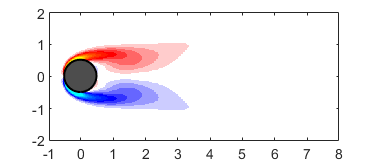

f2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


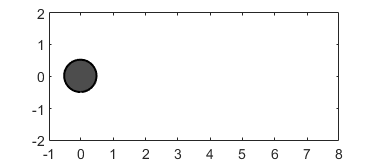

f2 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


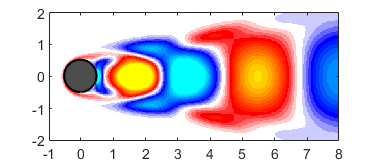

f2 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


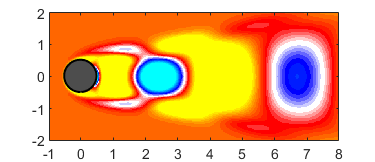

f2 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


f2 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


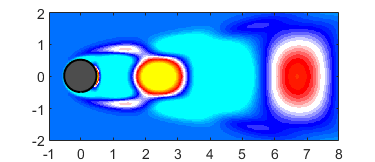

f2 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


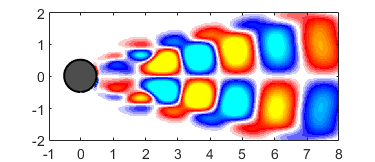

f2 =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


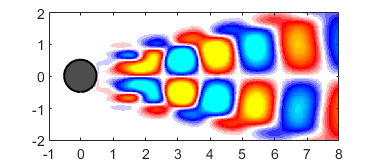

f2 =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


f2 =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


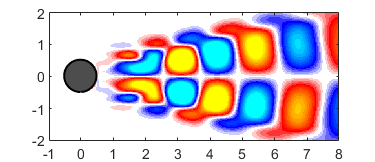

f2 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


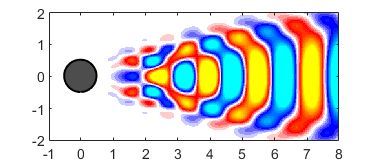

f2 =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


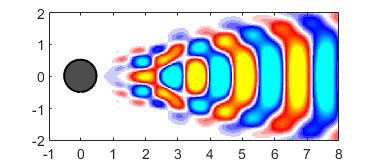

f2 =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


f2 =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


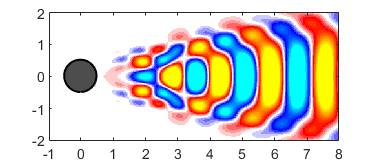

f2 =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


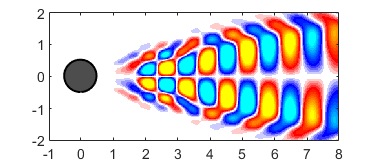

f2 =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


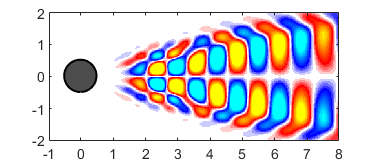

f2 =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


f2 =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


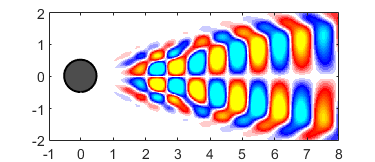

f2 =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


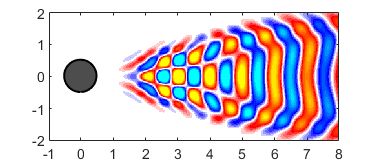

f2 =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


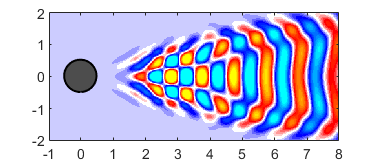

f2 =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


f2 =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


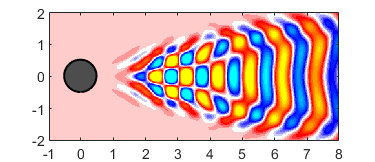

f2 =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


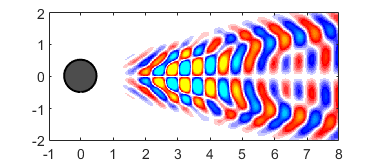

f2 =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


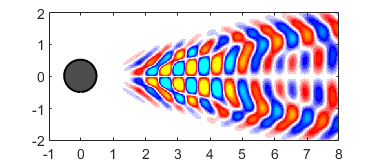

f2 =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


f2 =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


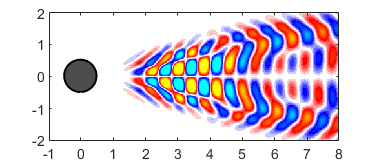

f2 =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


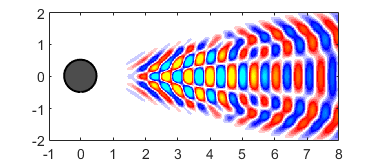

f2 =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


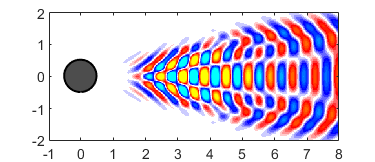

f2 =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


f2 =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


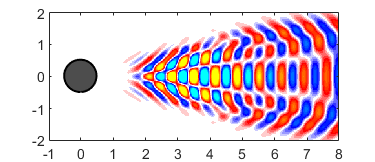

f2 =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


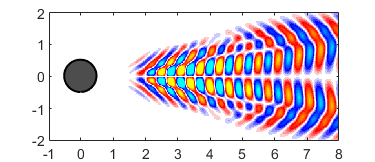

f2 =   Figure (33) with properties:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


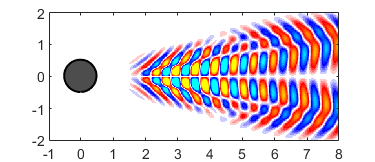

f2 =   Figure (34) with properties:

      Number: 34
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


f2 =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


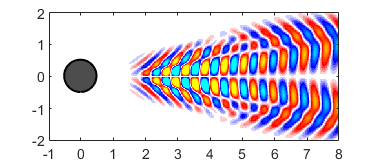

f2 =   Figure (36) with properties:

      Number: 36
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


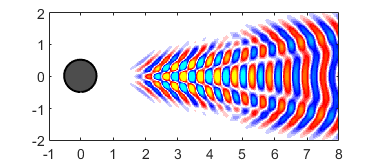

f2 =   Figure (37) with properties:

      Number: 37
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


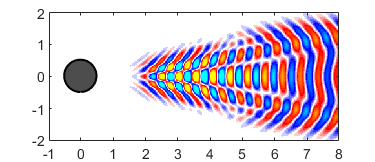

f2 =   Figure (38) with properties:

      Number: 38
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


f2 =   Figure (39) with properties:

      Number: 39
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


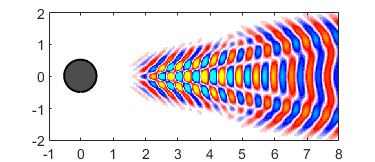

f2 =   Figure (40) with properties:

      Number: 40
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


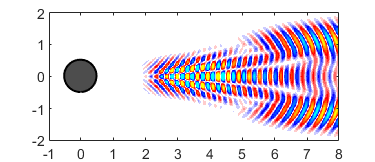

f2 =   Figure (41) with properties:

      Number: 41
        Name: ''
       Color: [1 1 1]
    Position: [100 100 300 130]
       Units: 'pixels'

  Show all properties


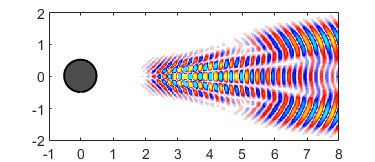

for i=1:20
plotCylinder(reshape(real (P(:,i)),nx,ny),nx,ny);
plotCylinder(reshape(imag (P(:,i)),nx,ny),nx,ny);
end

function f2 = plotCylinder(VORT,ny,nx)

f2 = figure
vortmin = -5;  % only plot what is in -5 to 5 range
vortmax = 5;
VORT(VORT>vortmax) = vortmax;  % cutoff at vortmax
VORT(VORT<vortmin) = vortmin;  % cutoff at vortmin

imagesc(VORT); % plot vorticity field
load CCcool.mat 
colormap(CC);  % use custom colormap

% clean up axes
set(gca,'XTick',[1 50 100 150 200 250 300 350 400 449],'XTickLabel',{'-1','0','1','2','3','4','5','6','7','8'})
set(gca,'YTick',[1 50 100 150 199],'YTickLabel',{'2','1','0','-1','-2'});
set(gcf,'Position',[100 100 300 130])
axis equal
hold on

% add contour lines (positive = solid, negative = dotted)
contour(VORT,[-5.5:.5:-.5 -.25 -.125],':k','LineWidth',1.2)
contour(VORT,[.125 .25 .5:.5:5.5],'-k','LineWidth',1.2)

theta = (1:100)/100'*2*pi;
x = 49+25*sin(theta);
y = 99+25*cos(theta);
fill(x,y,[.3 .3 .3])  % place cylinder
plot(x,y,'k','LineWidth',1.2) % cylinder boundary

set(gcf,'PaperPositionMode','auto') % 
% print('-depsc2', '-loose', 'figures/cylinder'); % eps are vector images
% fix_lines('figures/cylinder.eps','figures/cylinder.eps') % fix dashed lines
end